
I = fitsread("100p.fits");
%Ia = fitsread("1p.fits");
%Ib = fitsread("10p.fits");
%Ic = fitsread("50p.fits");
%imshow(I);
%imshow(Ia);
%imshow(Ib);
%imshow(Ic);

fontSize = 16;
fullFileName = "100p.fits"

fullFileName = "100p.fits"

grayImage = fitsread(fullFileName);
[row column colorSize] = size(grayImage);

% Get the dimensions of the image.  
% numberOfColorBands should be = 1.
size(grayImage)

ans =         2048        2048


%logzplot(Z,'colorbar')
X = [1:1:row];
Y = [1:1:column];
k = 1;
for i = (1:1:row)
    for j = (1:1:column)
        Z(i,j) = grayImage(i,j);
       
        if Z(i,j) < 0.5 
            Z(i,j) = Z(i,j);
            histData(k) = Z(i,j);
            k = k+1;
        else
            Z(i,j) = 0;
           %% histData(i*j) = Z(i,j);
            
        end
    end
end 
size(k)

ans =      1     1


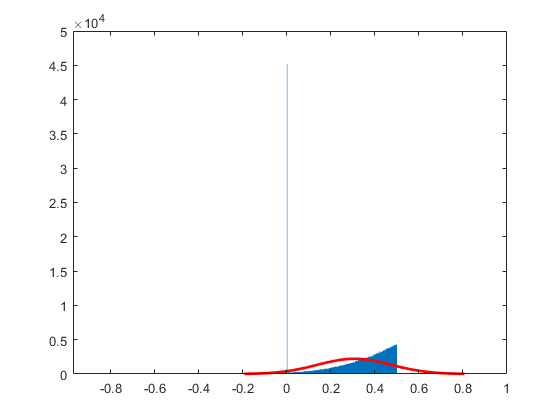

histfit(histData)

%%X=reshape(X(1:100),2048,2048);
%%Y=reshape(Y(1:100),2048,2048);
%%Z=reshape(Z(1:100),2048,2048);
%%[X,Y] = meshgrid(1:5:row:1:5:row);

%% X=reshape(x(1:100),10,10);
%%   Y=reshape(y(1:100),10,10);
%%   T=reshape(t(1:100),10,10);
% FIGURE
%%surf(X,Y,Z)
%%shading interp
%%colorbar

%cmap = colormap('hsv'); 

%colormap(jet(64))
%logzplot(X,Y,Z,'colorbar')

% Display the original gray scale image.
%subplot(2, 2, 1);
%imshow(grayImage, []);
%title('Original Grayscale Image', 'FontSize', fontSize);
% Enlarge figure to full screen.
%set(gcf, 'units','normalized','outerposition',[0 0 1 1]);
% Give a name to the title bar.
%set(gcf,'name','Demo by ImageAnalyst','numbertitle','off') 
%subplot(2,2,2);
%cmap = colormap("hsv");
%logzplot(grayImage)
%surf(grayImage)

%%fitsinfo(fullFileName)
%%fitsdisp(fullFileName)%
